cd("C:\Users\Bret Mecham\Lab\Bret")
participant_id = 3;
participant_datasets = MAV1Data{participant_id}

participant_datasets = 87×6 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0

valid_datasets = ~cellfun(@isempty, participant_datasets);
valid_datasets = find(valid_datasets(:,1));

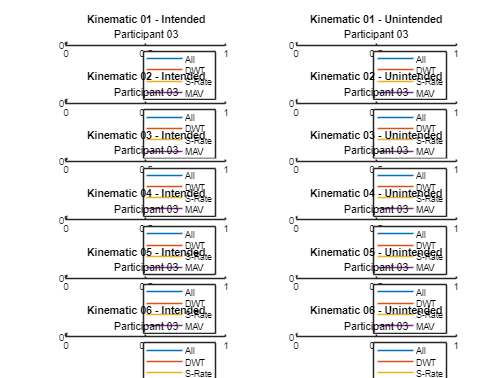

rmse indexing error 1 in dataset 87
rmse indexing error 2 in dataset 87
rmse indexing error 3 in dataset 87
kinematic indexing error 4 in dataset 87
rmse indexing error 4 in dataset 87
kinematic indexing error 5 in dataset 87
rmse indexing error 5 in dataset 87
rmse indexing error 6 in dataset 87


figure
tlo = tiledlayout(6,2);
for kinematic_idx = 1:6
[rmse_srate_traj, rmse_mav_traj, rmse_dwt_traj, rmse_all_traj] = extract_kinematic_rmse(kinematic_idx, participant_datasets, valid_datasets);
ax_h = nexttile;
rmse_idx = 1;
plot_rmse_trajectories(ax_h, rmse_all_traj, rmse_dwt_traj, rmse_srate_traj, rmse_mav_traj, rmse_idx)
title(sprintf("Kinematic %02d - Intended", kinematic_idx))
subtitle(sprintf("Participant %02d", participant_id))
legend
ax_h = nexttile;
rmse_idx = 2;
plot_rmse_trajectories(ax_h, rmse_all_traj, rmse_dwt_traj, rmse_srate_traj, rmse_mav_traj, rmse_idx)
title(sprintf("Kinematic %02d - Unintended", kinematic_idx))
subtitle(sprintf("Participant %02d", participant_id))
legend
end

## Helper Functions

function [rmse_srate_traj, rmse_mav_traj, rmse_dwt_traj, rmse_all_traj] = extract_kinematic_rmse(kinematic_idx, participant_datasets, valid_datasets)
% initialize variables to plot over time
N_RMSE = 2; % Intended and Unintended (Cross Talk)
rmse_srate_traj = nan(length(valid_datasets), N_RMSE);
rmse_mav_traj = nan(length(valid_datasets), N_RMSE);
rmse_dwt_traj = nan(length(valid_datasets), N_RMSE);
rmse_all_traj = nan(length(valid_datasets), N_RMSE);

for i =1:length(valid_datasets)
    dataset_idx = valid_datasets(i);
    rmse_flexion = participant_datasets{dataset_idx, 4};
    rmse_extension = participant_datasets{dataset_idx, 5};
    rmse_both = participant_datasets{dataset_idx, 6};
try
    rmse_srate = rmse_flexion{kinematic_idx, 7}{:};
    rmse_mav = rmse_flexion{kinematic_idx, 8}{:};
    rmse_dwt = rmse_flexion{kinematic_idx, 9}{:};
    rmse_all = rmse_flexion{kinematic_idx, 10}{:};
catch
    fprintf("kinematic indexing error %d in dataset %d\n", kinematic_idx, dataset_idx)
end
try
    rmse_srate_traj(i,:) = rmse_srate(1:2);
    rmse_mav_traj(i,:) = rmse_mav(1:2);
    rmse_dwt_traj(i,:) = rmse_dwt(1:2);
    rmse_all_traj(i,:) = rmse_all(1:2);
catch
    fprintf("rmse indexing error %d in dataset %d\n", kinematic_idx, dataset_idx)
end
end
end

function plot_rmse_trajectories(ax_h, rmse_all_traj, rmse_dwt_traj, rmse_srate_traj, rmse_mav_traj, rmse_idx)
hold on
plot(ax_h, rmse_all_traj(:,rmse_idx), 'DisplayName', "All")
plot(ax_h, rmse_dwt_traj(:,rmse_idx), 'DisplayName', "DWT")
plot(ax_h, rmse_srate_traj(:,rmse_idx), 'DisplayName', "S-Rate")
plot(ax_h, rmse_mav_traj(:,rmse_idx), 'DisplayName', "MAV")
hold off

end